# Height of Ribbon Tilings

## Data input.

x and y are coordinates of the points, and v is the height vector at these points. 

n = 3; %size of ribbon tiles
%h = load('Height_Aztec_20_100000.txt')
%h = load('Height_Aztec_20_1.txt')
h0 = load(['Height_Square_21_1.txt'])

h0 =      0     0     0     0     0
     0     1    -1     0     1
     1     0     1     0    -1
     0     2     0    -1     1
     1     1     2    -1    -1
     2     0     0     1    -1
     0     3     0     0     0
     1     2     2     0    -2
     2     1     0     2    -2
     3     0     0     0     0


x0 = h0(:,1); y0 = h0(:,2); v0 = h0(:,3 : n + 2);
h = load(['Height_Square_21_100000.txt'])

h =      0     0     0     0     0
     0     1    -1     0     1
     1     0     1     0    -1
     0     2     0    -1     1
     1     1    -2     1     1
     2     0     0     1    -1
     0     3     0     0     0
     1     2     0    -2     2
     2     1    -2     0     2
     3     0     0     0     0


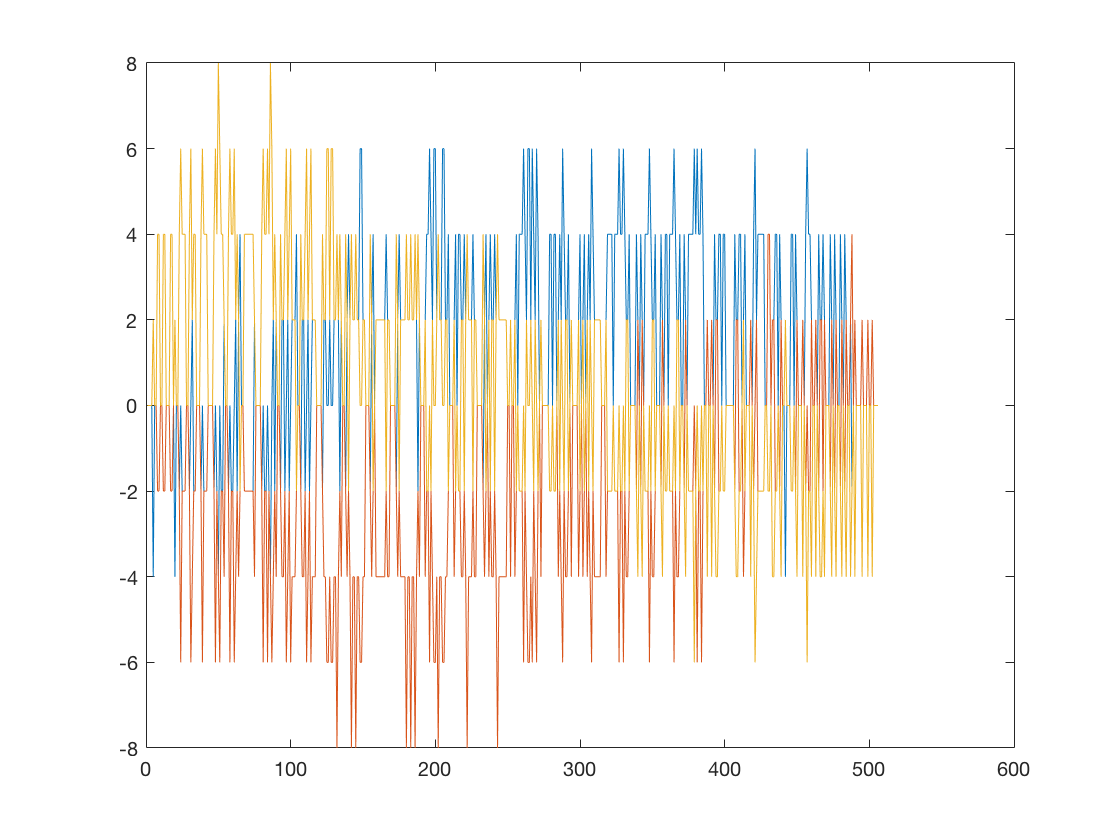

x = h(:,1); y = h(:,2); v = h(:,3 : n + 2);
plot(v - v0)

[xq,yq] = meshgrid(0:0.1:max(x), 0:0.1:max(y));

## Plot of the first component

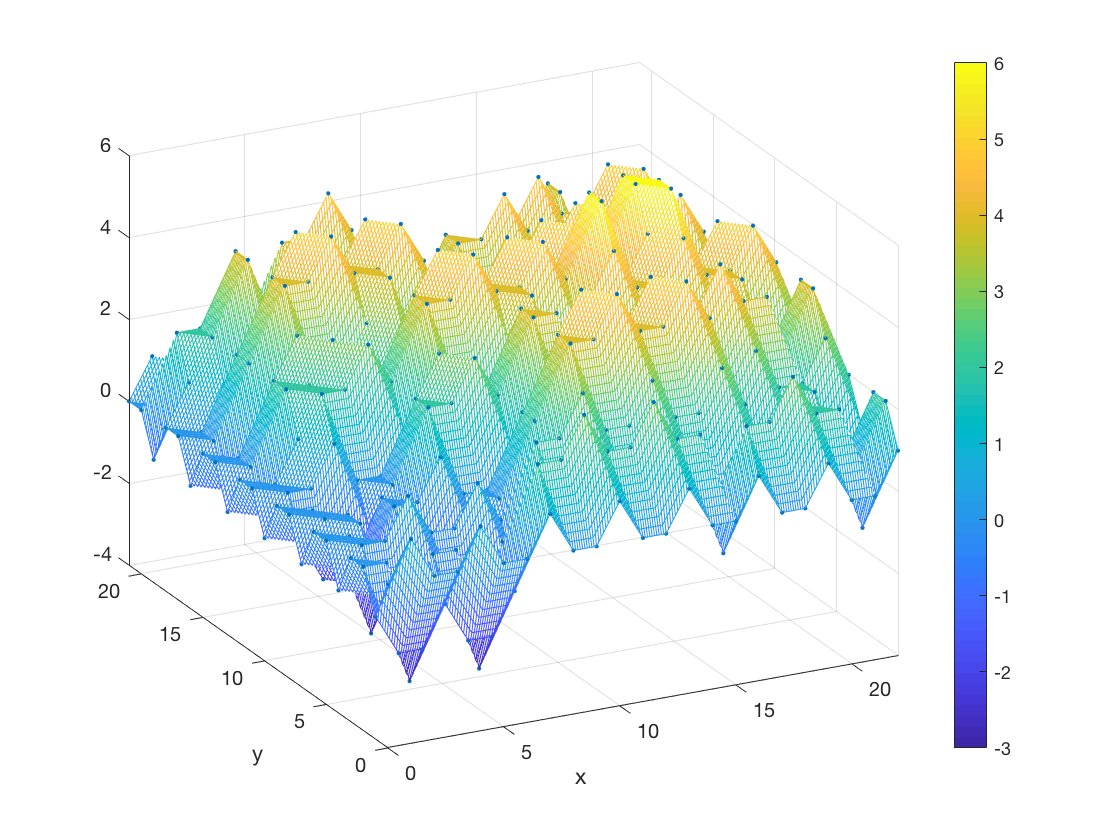

vq = griddata(x,y,v(:,1),xq,yq);
figure(1)
mesh(xq,yq,vq)
hold on
plot3(x,y,v(:,1),'.')
xlim([0 max(x)])
ylim([0 max(y)])
colorbar
xlabel('x')
ylabel('y')

view([-26.9 26.6])

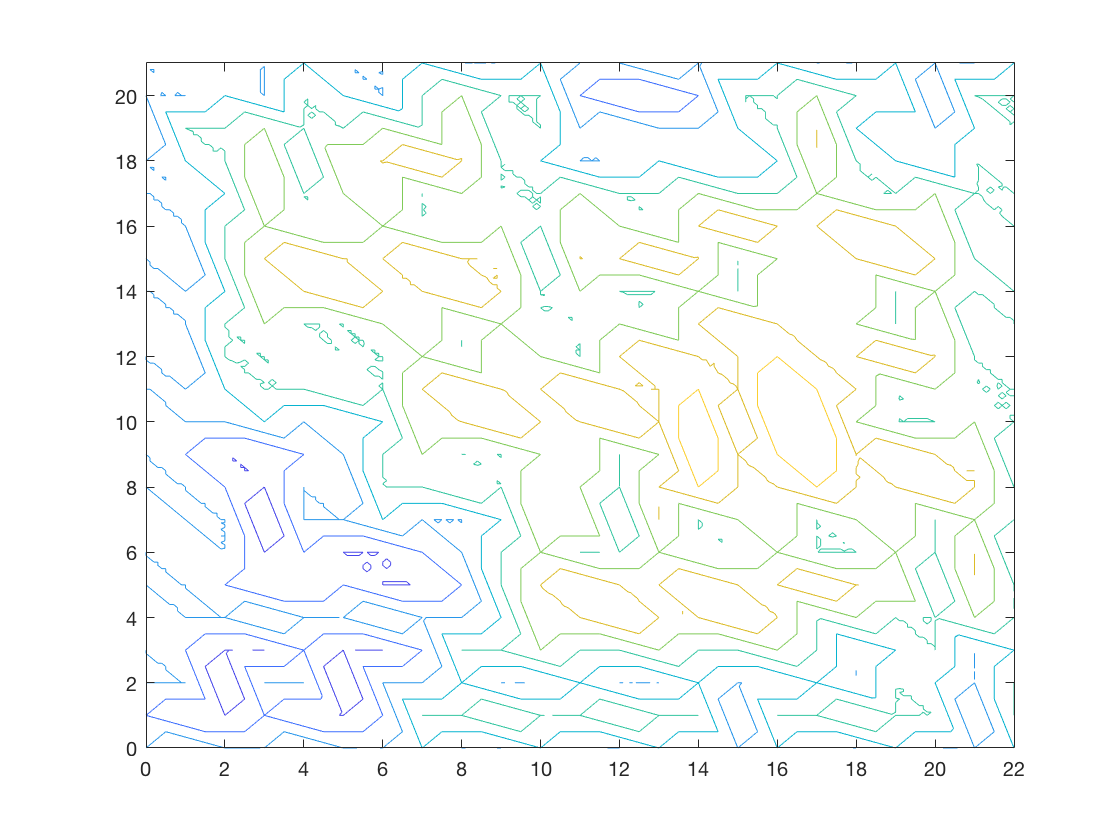


figure(2)
contour(xq,yq,vq);

## Plot of the second component

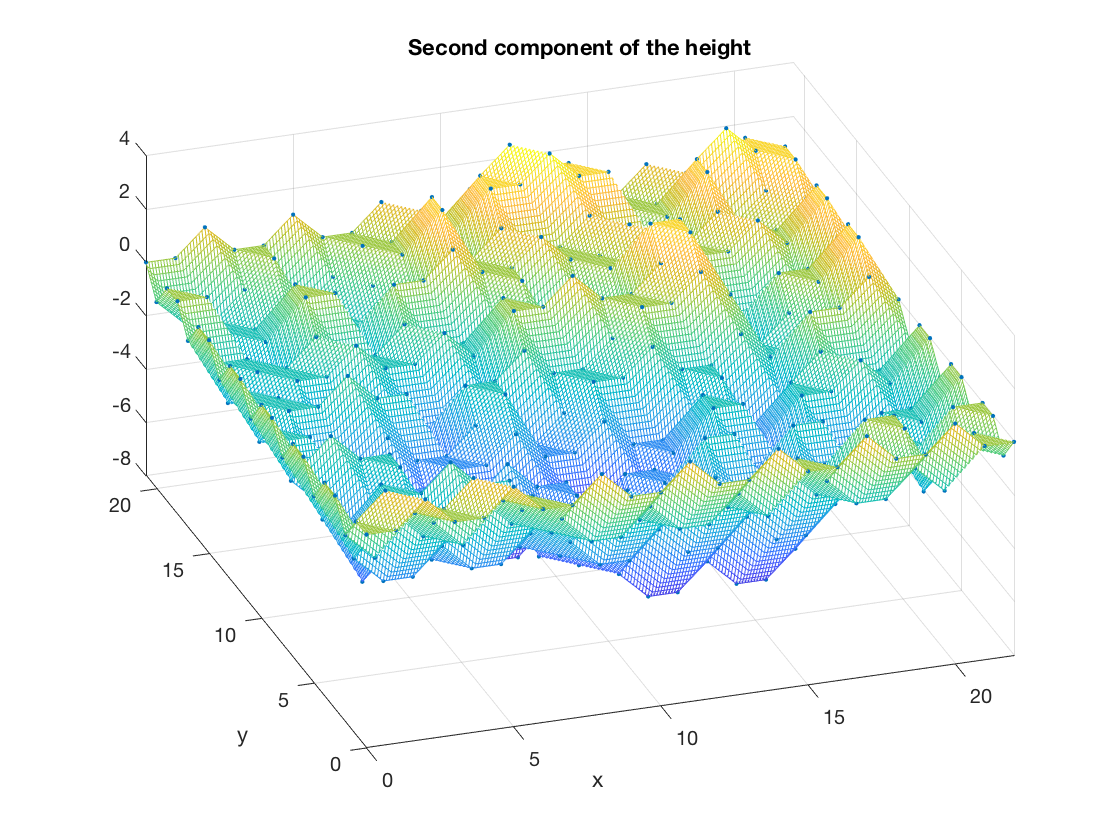

vq = griddata(x,y,v(:,2),xq,yq);
figure(3)
mesh(xq,yq,vq)
hold on
plot3(x,y,v(:,2),'.')
xlim([0 max(x)])
ylim([0 max(y)])

view([-18.8 41.9])
title('Second component of the height')
xlabel('x')
ylabel('y')

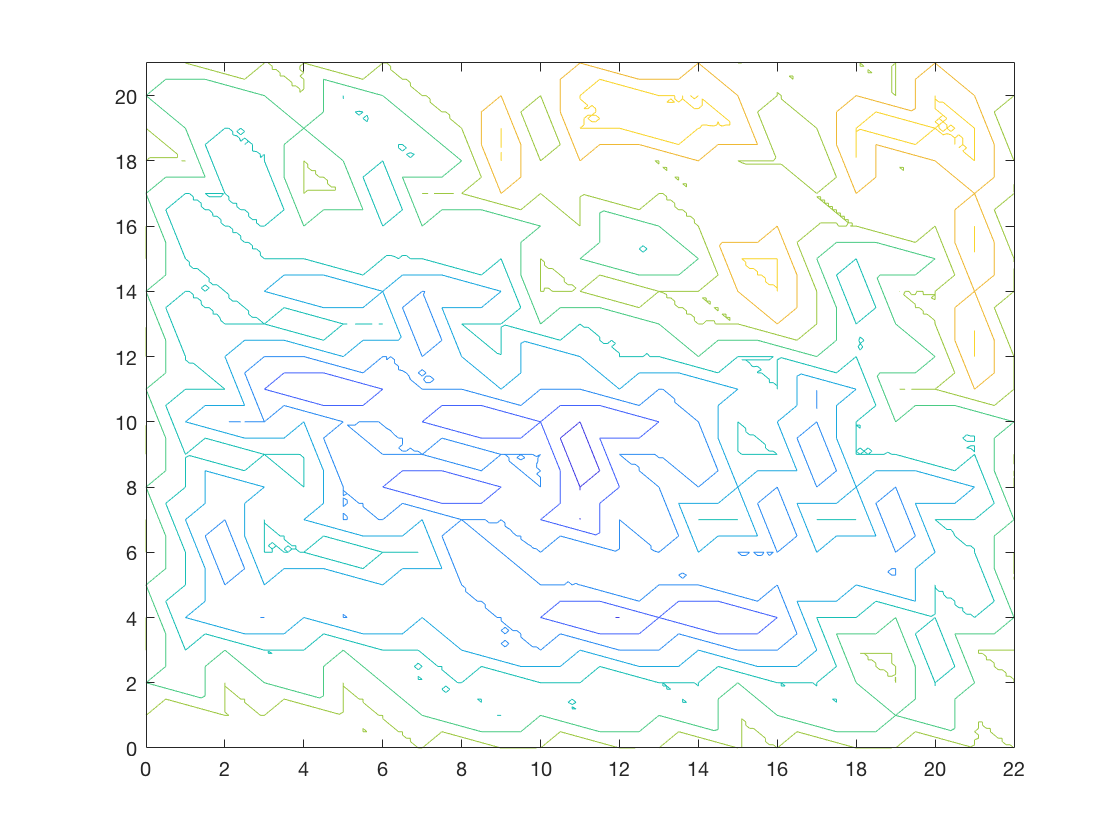

figure(4)
contour(xq,yq,vq);

%ind = find(x + y == 20);
ind = find(y == 0)

ind =      1
     3
     6
    10
    15
    21
    28
    36
    45
    55


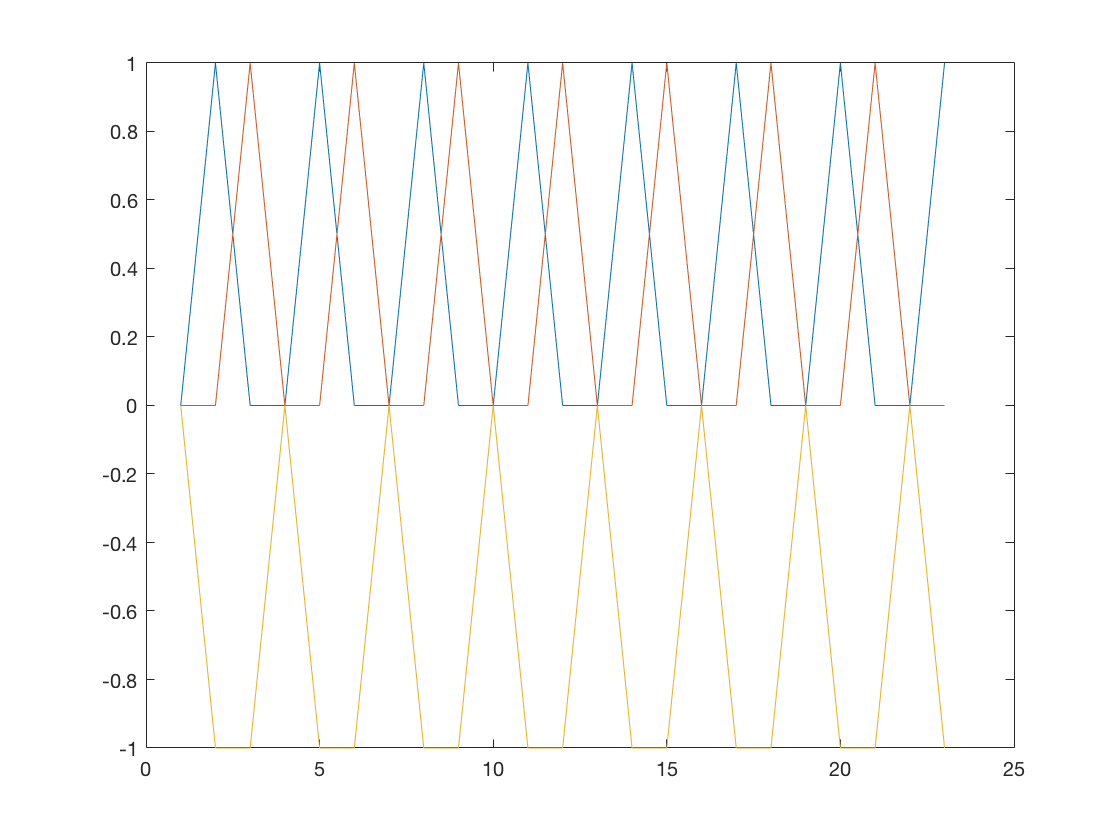

hrestr = v(ind, :);
plot(hrestr);